%examples_mixture_generation shows a series of examples about mixture generation with prespecified overlapping
%
% Data are simulated from normal mixture distributions on the basis of
% pre-specified synthesis statistics on an overlap measure defined as
% function of pairwise misclassification probabilities. The reference paper is
%
%   Melnykov, V., Chen, W.-C., and Maitra, R. (2012) MixSim: An R Package
%   for Simulating Data to Study Performance of Clustering Algorithms,
%   Journal of Statistical Software, 51:12, 1-25. (to refer to
%   this publication we will use "MCM2012 JSS")
%
% Description: MixSim allows simulating mixtures of Gaussian distributions
% with different levels of overlap between mixture components.  Pairwise
% overlap, defined as a sum of two misclassification probabilities,
% measures the degree of interaction between components and can be readily
% employed to control the clustering complexity of datasets simulated in
% each example.
%
% In order to check the consistency of results with the examples contained
% in the R MixSim library it is possible to set up a connection with R in
% order to use the data generated directly from R and used in MCM2012 JSS
%
% See file Connect_Matlab_with_R_HELP.m contined in subfolder clustering of
% the FSDA toolbox to find out how to execute R commands from within
% MATLAB.
%
% In the original MixSim formulation, the user can specify the
% desired maximum and/or average overlap values for k groups in v
% dimensions. However,  given that  very different clustering scenarios can
% produce the same value of maximum and/or average overlap, we have
% extended the control of the generated mixtures to the overlapping
% standard deviation. We can now generate overlapping groups by fixing up
% to two of the three statistics.
%
% We have also introduced a new constraint on the eigenvalues of the
% covariance matrices in order to control the ratio among the lengths of
% the ellipsoids axes associated with the groups (i.e. departures from
% sphericity) and the relative cluster sizes. This new \textsc{MixSim}
% feature allows to simulate data which comply with the TCLUST model of
%
%  Garcia-Escudero, L.A.; Gordaliza, A.; Matran, C. and Mayo-Iscar, A.
%  (2008), "A General Trimming Approach to Robust Cluster Analysis". Annals
%  of Statistics, Vol.36, 1324-1345. Technical Report available at
%  www.eio.uva.es/inves/grupos/representaciones/trTCLUST.pdf.
%  See function tclust.m contained in the toolbox
%
%
% Copyright 2008-2016.
% Written by FSDA team

% Last modified 31-05-2016

## Generate 5 groups in 7 dimensions controlling average and maximum overlapping

clearvars -except RandomDataFromR; close all;

% RandomDataFromR is a boolean which enables to specify whether the random
% numbers bust be generated directly from R (in this case the MATLAB R
% connection has to be installed) or from MATLAB.
%
RandomDataFromR=false;

if RandomDataFromR == true
    
    chkMatlab_With_R_connection=exist('openR','file');
    if chkMatlab_With_R_connection==0
        disp('Connection with R has not been setup yet')
        examp=which('Connect_Matlab_with_R_HELP.m');
        examp1=strrep(examp,'\','\\');
        stri=['See file Connect_Matlab_with_R_HELP.m  for more information'];
        disp(stri)
    end
    
    R_seed = 1234;
    if R_seed
        [~] = evalR(['set.seed(' num2str(R_seed) ', kind=''Mersenne-Twister'', normal.kind = ''Inversion'')']);
    end
    
else
    R_seed=0;
end

fail = 1;
while fail
    Q = MixSim(5, 7, 'BarOmega' , 0.01, 'MaxOmega' , 0.05, 'R_seed', R_seed);
    fail = Q.fail;
end

% [OmegaMap, BarOmega, MaxOmega, StdOmega, rcMax] = overlap(5, 7, Q.Pi, Q.Mu, Q.S);
disp('Map of misclassification probabilities')

Map of misclassification probabilities


disp(Q.OmegaMap);

    1.0000    0.0015    0.0011    0.0059    0.0038
    0.0015    1.0000    0.0010    0.0021    0.0232
    0.0009    0.0011    1.0000    0.0035    0.0007
    0.0055    0.0025    0.0040    1.0000    0.0051
    0.0052    0.0268    0.0009    0.0038    1.0000



disp('Average overlap among groups')

Average overlap among groups


disp(Q.BarOmega);

    0.0100



disp('Maximum overlap among groups')

Maximum overlap among groups


disp(Q.MaxOmega);

    0.0500



disp('Standard deviation of overlap among groups')

Standard deviation of overlap among groups


disp(Q.StdOmega);

    0.0145



disp('Indexes of the two groups producing the highest overlap')

Indexes of the two groups producing the highest overlap


disp(Q.rcMax);

     2
     5



## Example 1 of Section 3.1 "MCM2012 JSS", 4 groups in 5 dimensions with prespecified average and maximum overlapping

clearvars -except RandomDataFromR; close all;
if RandomDataFromR == true
    R_seed = 1234;
    
    if R_seed
        [~] = evalR(['set.seed(' num2str(R_seed) ', kind=''Mersenne-Twister'', normal.kind = ''Inversion'')']);
    end
else
    R_seed=0;
end

ex1 = MixSim(4, 5, 'BarOmega' , 0.05, 'MaxOmega' , 0.15, 'R_seed', R_seed);

## Example 2 of Section 3.1, 3 spherical components in two dimensions and a control on mixture proportions

clearvars -except RandomDataFromR; close all;
if RandomDataFromR == true
    R_seed = 1234;
    if R_seed
        [~] = evalR(['set.seed(' num2str(R_seed) ', kind=''Mersenne-Twister'', normal.kind = ''Inversion'')']);
    end
    
else
    R_seed=0;
end

ex2 = MixSim(3, 2, 'MaxOmega' , 0.1, 'sph' , true, 'PiLow' , 0.1, 'R_seed', R_seed);

## Example 3 of Section 3.1, 2 homogeneous spherical components in two dimensions

clearvars -except RandomDataFromR; close all;
if RandomDataFromR == true
    R_seed = 1234;
    if R_seed
        [~] = evalR(['set.seed(' num2str(R_seed) ', kind=''Mersenne-Twister'', normal.kind = ''Inversion'')']);
    end
else
    R_seed=0;
end

ex3 = MixSim(2, 4, 'BarOmega' , 0.05, 'sph' , true, 'hom' , true,  'tol', [1e-10 1e-10], 'int', [0 10], 'R_seed', R_seed);

## Example for Section 3.2, analysis of degree of overlapping of Fisher Iris data

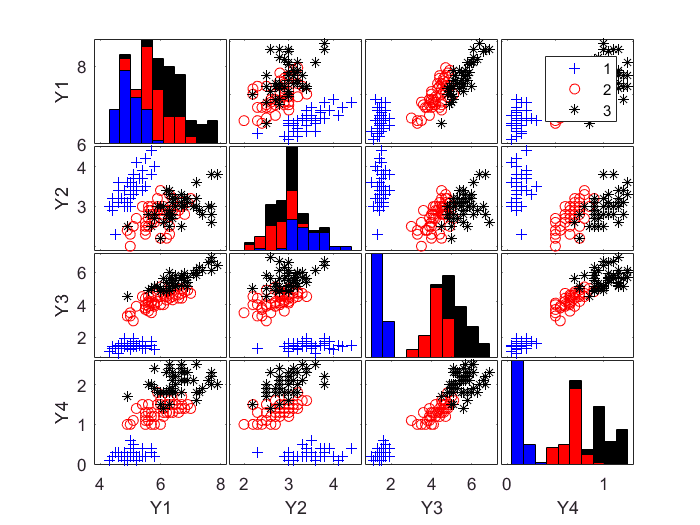

clearvars -except RandomDataFromR; close all;
% iris data
Y=load('ir.txt');
p=size(Y,2);
gr=repmat(1:3,50,1);
id=gr(:);
spmplot(Y,id);

K = max(id);

%estimate mixture parameters
t = tabulate(id);
Pi = t(:,3);
Mu = grpstats(Y,id,{'mean'});
S(:,:,1) = cov(Y(id==1,:));
S(:,:,2) = cov(Y(id==2,:));
S(:,:,3) = cov(Y(id==3,:));

% overlap
[OmegaMap, BarOmega, MaxOmega, StdOmega, rcMax] = overlap(K, p, Pi, Mu, S); %#ok<ASGLU>

## Example 1 of Section 3.3 plot (a), 500 observations generated from 5 groups with prespecified maximum and average overlap

clearvars -except RandomDataFromR; close all;
if RandomDataFromR == true
    R_seed = 1234;
    if R_seed
        [~] = evalR(['set.seed(' num2str(R_seed) ', kind=''Mersenne-Twister'', normal.kind = ''Inversion'')']);
    end
else
    R_seed=0;
end

Q1a = MixSim(5, 2, 'MaxOmega' , 0.20, 'BarOmega' , 0.05, 'R_seed', R_seed);

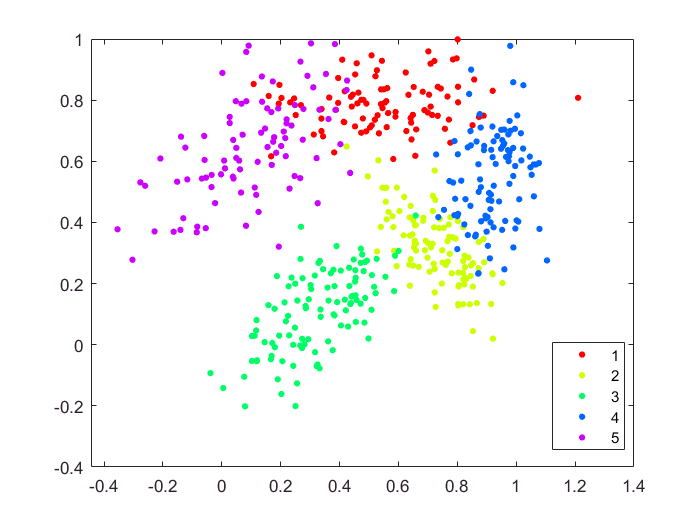

[A1a , id1a] = simdataset(500, Q1a.Pi, Q1a.Mu, Q1a.S, 'R_seed', R_seed);

gscatter(A1a(:,1),A1a(:,2),id1a);

## Example 1 of Section 3.3 plot (b), 500 observations generated from 2 groups in two dimensions with prespecified maximum and average overlap

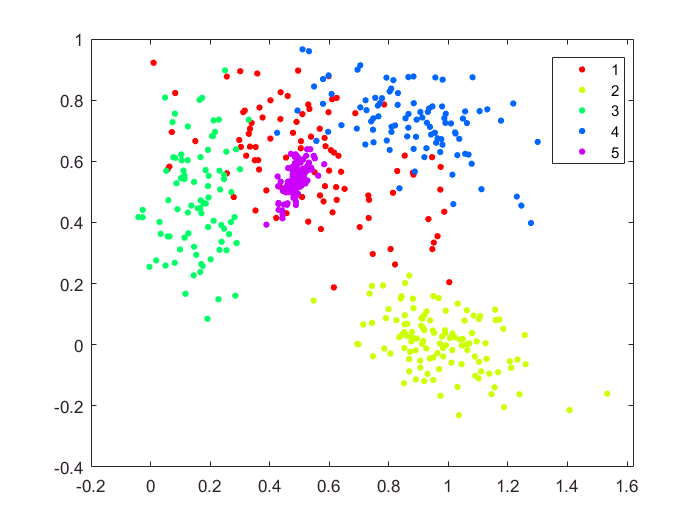

clearvars -except RandomDataFromR; close all;
if RandomDataFromR == true
    R_seed = 1235;
    if R_seed
        [~] = evalR(['set.seed(' num2str(R_seed) ', kind=''Mersenne-Twister'', normal.kind = ''Inversion'')']);
    end
else
    R_seed=0;
end

Q1b = MixSim(5, 2, 'MaxOmega' , 0.20, 'BarOmega' , 0.05, 'R_seed', R_seed);
[A1b , id1b] = simdataset(500, Q1b.Pi, Q1b.Mu, Q1b.S, 'R_seed', R_seed);

gscatter(A1b(:,1),A1b(:,2),id1b);

## Example 2 of Section 3.3 plot (b), 500 observations generated from 5 groups in two dimensions with prespecified maximum and average overlap

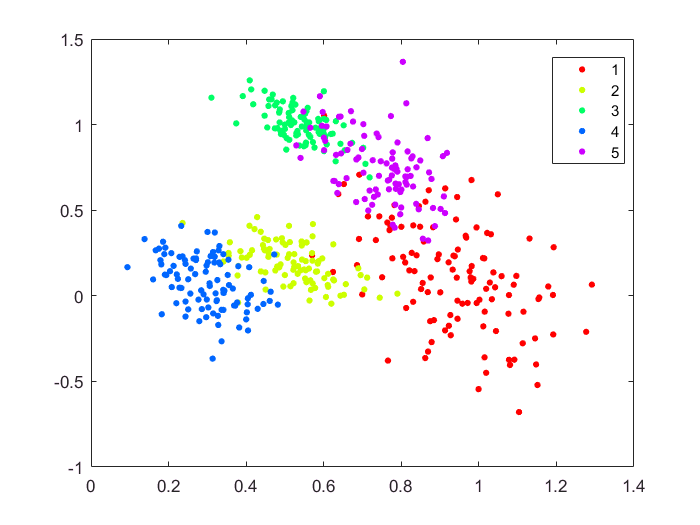

clearvars -except RandomDataFromR; close all;
if RandomDataFromR == true
    R_seed = 1238;
    if R_seed
        [~] = evalR(['set.seed(' num2str(R_seed) ', kind=''Mersenne-Twister'', normal.kind = ''Inversion'')']);
    end
else
    R_seed=0;
end

Q2 = MixSim(5, 2, 'MaxOmega' , 0.20, 'BarOmega' , 0.05, 'R_seed', R_seed);
[A2 , id2] = simdataset(500, Q2.Pi, Q2.Mu, Q2.S, 'R_seed', R_seed);

gscatter(A2(:,1), A2(:,2), id2);

## Example 2 of Section 3.3 plot (c), 300 observations in 2 dimensions with prespecififed max overlap, transformed using Box Cox

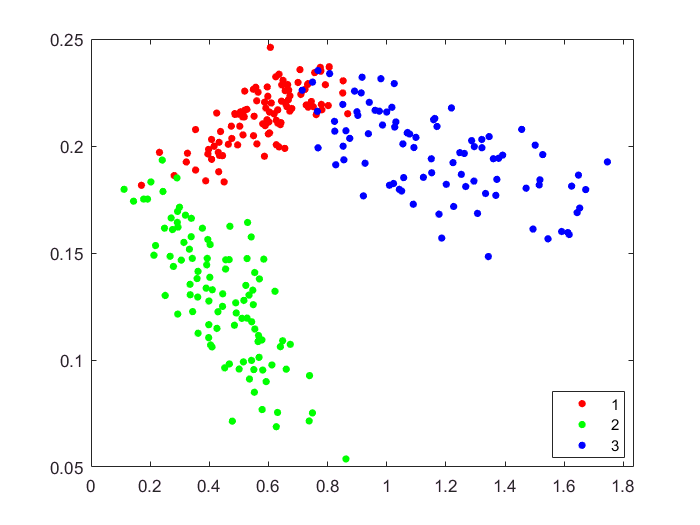

clearvars -except RandomDataFromR; close all;
if RandomDataFromR == true
    R_seed = 1238;
    if R_seed
        [~] = evalR(['set.seed(' num2str(R_seed) ', kind=''Mersenne-Twister'', normal.kind = ''Inversion'')']);
    end
else
    R_seed=0;
end

Q3 = MixSim(3, 2, 'MaxOmega' , 0.1, 'int', [0.2 1], 'R_seed', R_seed);
[A3 , id3] = simdataset(300, Q3.Pi, Q3.Mu, Q3.S, 'lambda' , [0.1 10],'R_seed', R_seed);

gscatter(A3(:,1), A3(:,2), id3);

## Example 2 of Section 3.3 plot (d), 300 observations in 2 dimensions with prespecififed max overlap, transformed using Box Cox

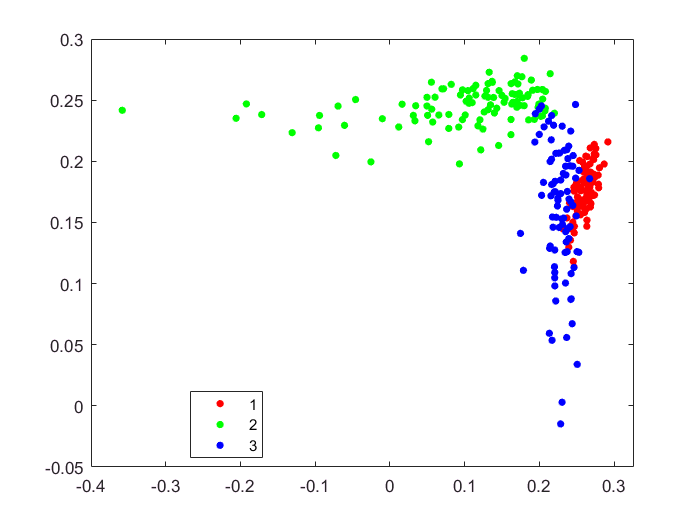

clearvars -except RandomDataFromR; close all;

if RandomDataFromR == true
    R_seed = 1238;
    if R_seed
        [~] = evalR(['set.seed(' num2str(R_seed) ', kind=''Mersenne-Twister'', normal.kind = ''Inversion'')']);
    end
else
    R_seed=0;
end

Q4 = MixSim(3, 2, 'MaxOmega' , 0.1, 'int', [0.2 1], 'R_seed', R_seed);
[A4 , id4] = simdataset(300, Q4.Pi, Q4.Mu, Q4.S, 'lambda' , [10 10],'R_seed', R_seed);

gscatter(A4(:,1) , A4(:,2), id4);

## Example 3 of Section 3.3 plot (a), 500 observations in 2 dimensions with prespecififed max overlap, transformed using Box Cox + 10 outliers

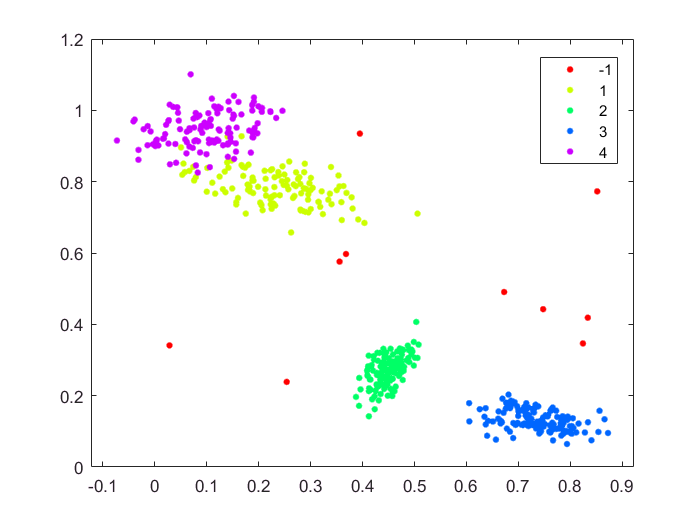

clearvars -except RandomDataFromR; close all;
if RandomDataFromR == true
    R_seed = 1234;
    if R_seed
        [~] = evalR(['set.seed(' num2str(R_seed) ', kind=''Mersenne-Twister'', normal.kind = ''Inversion'')']);
    end
else
    R_seed=0;
end

Q5 = MixSim(4, 2, 'BarOmega' , 0.01, 'R_seed', R_seed);
[A5 , id5] = simdataset(500, Q5.Pi, Q5.Mu, Q5.S, 'noiseunits',10,'R_seed', R_seed);
gscatter(A5(:,1), A5(:,2), id5);

## Example 3 of Section 3.3 plot (b), 500 observations in 2 dimensions with prespecififed average overlap + 10 outliers

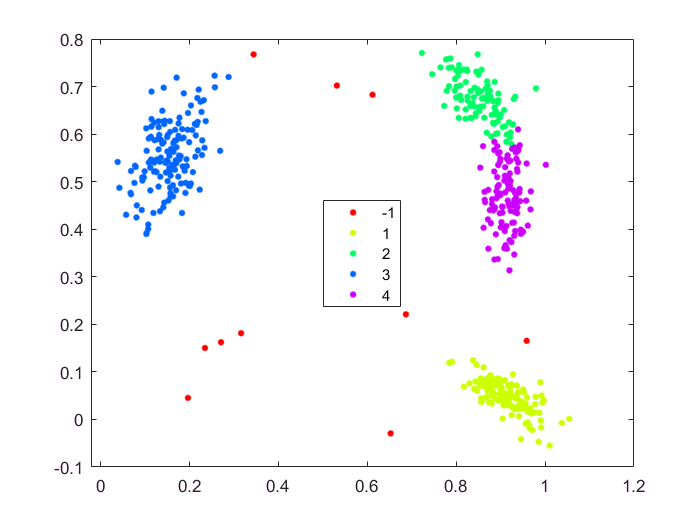

clearvars -except RandomDataFromR; close all;
if RandomDataFromR == true
    R_seed = 1237;
    if R_seed
        [~] = evalR(['set.seed(' num2str(R_seed) ', kind=''Mersenne-Twister'', normal.kind = ''Inversion'')']);
    end
else
    R_seed=0;
end

Q6 = MixSim(4, 2, 'BarOmega' , 0.01, 'R_seed', R_seed);
[A6 , id6] = simdataset(500, Q6.Pi, Q6.Mu, Q6.S, 'noiseunits',10,'R_seed', R_seed);
gscatter(A6(:,1), A6(:,2), id6);

## Example 4 of Section 3.3 plot (c), 300 observations in 1 dimension with prespecififed max overlap + 1 noise variable

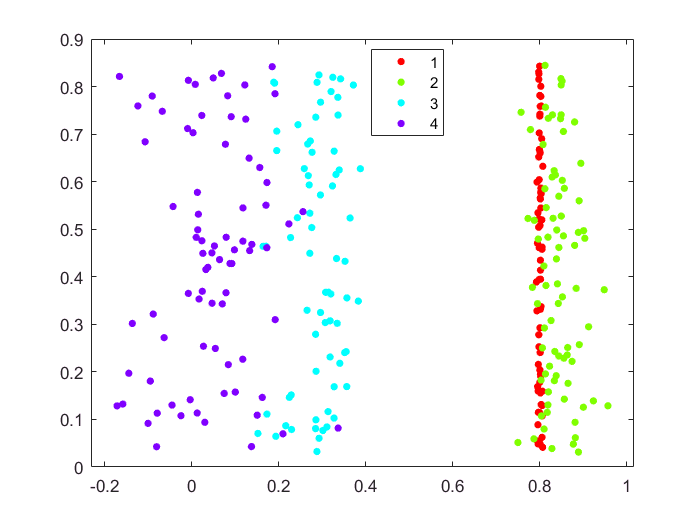

clearvars -except RandomDataFromR; close all;
if RandomDataFromR == true
    R_seed = 1235;
    if R_seed
        [~] = evalR(['set.seed(' num2str(R_seed) ', kind=''Mersenne-Twister'', normal.kind = ''Inversion'')']);
    end
else
    R_seed=0;
end

Q7 = MixSim(4, 1, 'MaxOmega' , 0.1, 'R_seed', R_seed);
[A7 , id7] = simdataset(300, Q7.Pi, Q7.Mu, Q7.S, 'noisevars',1,'R_seed', R_seed);
gscatter(A7(:,1), A7(:,2), id7);

## Example 4 of Section 3.3 plot (c) bis "MCM2012 JSS"

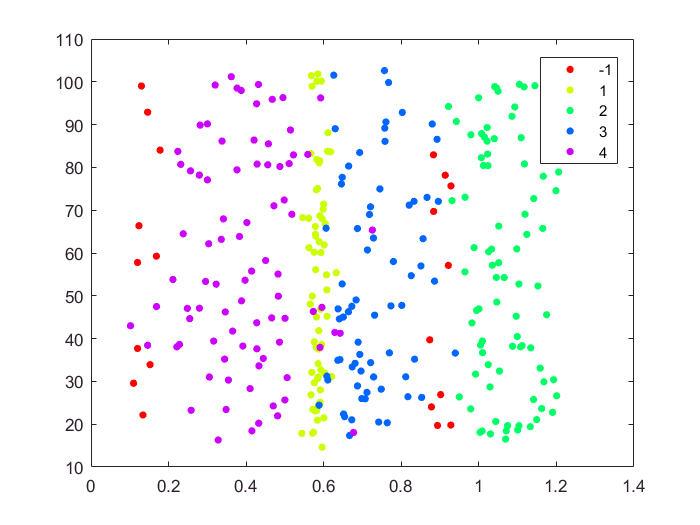

clearvars -except RandomDataFromR; close all;
% Same as cell above but with all options for simdataset
if RandomDataFromR == true
    R_seed = 1235;
    if R_seed
        [~] = evalR(['set.seed(' num2str(R_seed) ', kind=''Mersenne-Twister'', normal.kind = ''Inversion'')']);
    end
else
    R_seed=0;
end

Q7 = MixSim(4, 1, 'MaxOmega' , 0.1, 'R_seed', R_seed);

noiseunits=struct;
noiseunits.number=20;
noiseunits.alpha=0.1;
noiseunits.maxiter=100;
noisevars=struct;
noisevars.number=1;
noisevars.interval=[10; 50];
[A7 , id7] = simdataset(300, Q7.Pi, Q7.Mu, Q7.S, 'noisevars',noisevars,'noiseunits',noiseunits,'lambda',[0.5 0.8],'R_seed', R_seed);
gscatter(A7(:,1), A7(:,2), id7);

% To run the code above in R please use the following sintax
% set.seed(1235, kind='Mersenne-Twister' , normal.kind = 'Inversion')
% Q <- MixSim(MaxOmega = 0.1, K = 4, p = 1)
% A <- simdataset(n = 300, Pi = Q$Pi, Mu = Q$Mu, S = Q$S,
%                 n.noise = 1, n.out = 20, alpha = 0.1,
%                 int = c(10,50), lambda = c(0.5,0.8), max.out = 100)

## Example 4 of Section 3.3 plot (d) 300 observations in 1 dimension with prespecififed max overlap + 1 noise variable

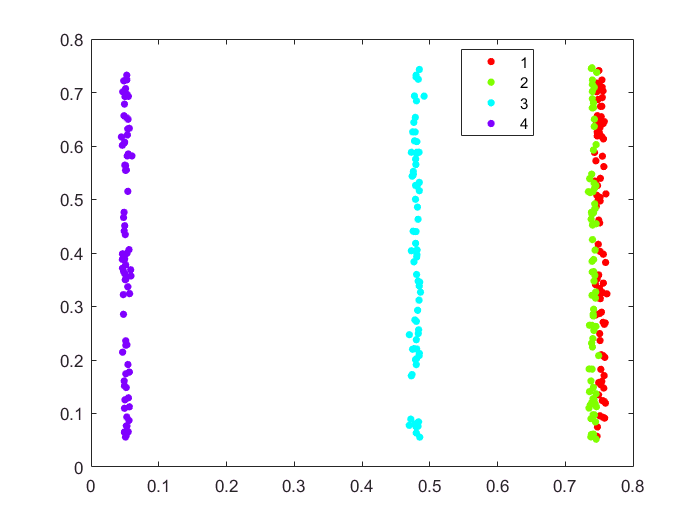

clearvars -except RandomDataFromR; close all;
if RandomDataFromR == true
    R_seed = 1236;
    if R_seed
        [~] = evalR(['set.seed(' num2str(R_seed) ', kind=''Mersenne-Twister'', normal.kind = ''Inversion'')']);
    end
else
    R_seed=0;
end

Q8 = MixSim(4, 1, 'MaxOmega' , 0.1, 'R_seed', R_seed);
[A8 , id8] = simdataset(300, Q8.Pi, Q8.Mu, Q8.S, 'noisevars',1,'R_seed', R_seed);
gscatter(A8(:,1), A8(:,2), id8);

## Example of Section 3.4 plot (a) "MCM2012 JSS"

clearvars -except RandomDataFromR; close all;
% this cell demos the pdplot: not yet implemented

% iris data
Y=load('ir.txt');
p=size(Y,2);
gr=repmat(1:3,50,1);
id=gr(:);
spmplot(Y,id);

K = max(id);

%estimate mixture parameters
t = tabulate(id);
Pi = t(:,3);
Mu = grpstats(Y,id,{'mean'}); %#ok<NASGU>
S(:,:,1) = cov(Y(id==1,:));
S(:,:,2) = cov(Y(id==2,:));
S(:,:,3) = cov(Y(id==3,:)); %#ok<NASGU>

%pdplot, not yet implemented
%pdplot(Pi, Mu, S);

## Example of Section 3.4 plot (b), 6 groups in 4 dimensions with prespecified average overlap

clearvars -except RandomDataFromR; close all;
if RandomDataFromR == true
    R_seed = 1234;
    if R_seed
        [~] = evalR(['set.seed(' num2str(R_seed) ', kind=''Mersenne-Twister'', normal.kind = ''Inversion'')']);
    end
else
    R_seed=0;
end

Q9 = MixSim(6, 4, 'BarOmega' , 0.001, 'R_seed', R_seed);

## Example of Section 3.4 plot (c), 6 groups in 4 dimensions with prespecified average overlap

clearvars -except RandomDataFromR; close all;
if RandomDataFromR == true
    R_seed = 1232;
    if R_seed
        [~] = evalR(['set.seed(' num2str(R_seed) ', kind=''Mersenne-Twister'', normal.kind = ''Inversion'')']);
    end
else
    R_seed=0;
end

Q10 = MixSim(6, 4, 'BarOmega' , 0.05, 'R_seed', R_seed);

## close connection with R

if RandomDataFromR == true
    
    if R_seed
        closeR;
    end
    
else
    R_seed=0;
end

## Generate clusters controlling average, maximum overlap and eigenvalues ratio contraint

% Example of use of optional input option restrfactor. In the first case
% restrfactor is 1.1 and the clusters are roughly homogeneous. In the
% second case no constraint is imposed on the ratio of maximum and
% minimum eigevalue among clusters so elliptical shape clusters are
% allowed. In both cases the same random seed together with the same level
% of average and maximum overlapping is used
clearvars -except RandomDataFromR; close all;
rng('default')
rng(2);
out=MixSim(3,5,'BarOmega',0.1, 'MaxOmega',0.2, 'restrfactor',1.1);

rng(2);
out1=MixSim(3,5,'BarOmega',0.1, 'MaxOmega',0.2);

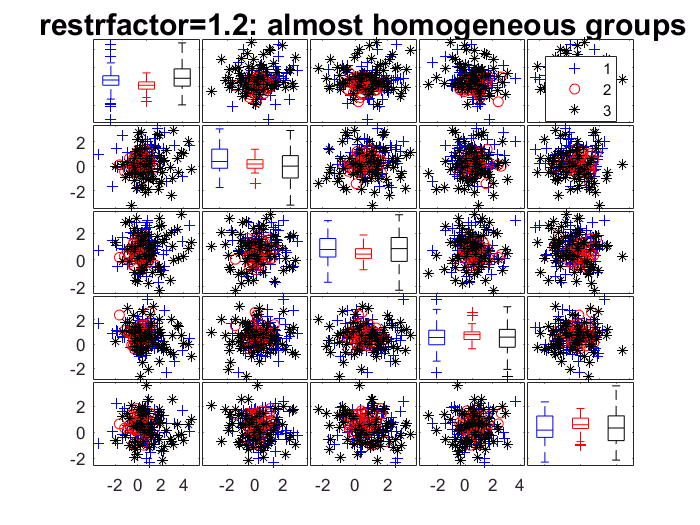

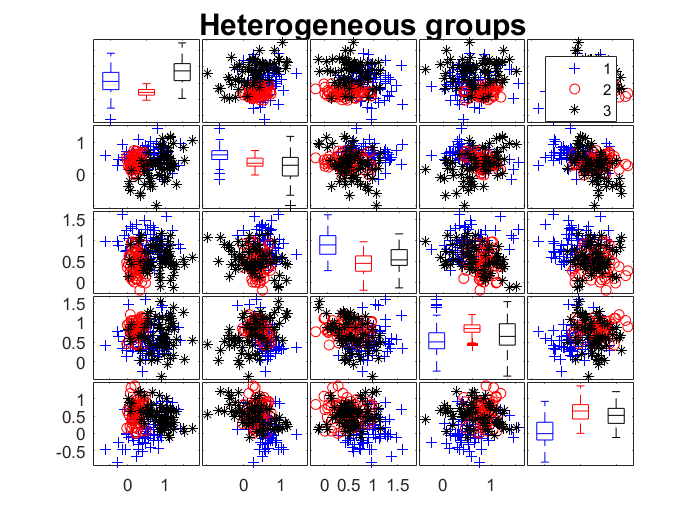


n=200;
[X,id]=simdataset(n, out.Pi, out.Mu, out.S);
spmplot(X,id,[],'box');
title('restrfactor=1.2: almost homogeneous groups','fontsize',18);
set(gcf,'Name','restrfactor=1.2: almost homogeneous groups')

[X1,id1]=simdataset(n, out1.Pi, out1.Mu, out1.S);
figure;
spmplot(X1,id1,[],'box');
title('Heterogeneous groups','fontsize',18)
set(gcf,'Name','Heterogeneous groups')
cascade

disp('Comparison using interactive scatter plot matrices')

Comparison using interactive scatter plot matrices


disp('Please click on the legends to hide/show groups')

Please click on the legends to hide/show groups


## Generate clusters controlling average and standard deviation of overlap

clearvars -except RandomDataFromR; close all;
rng(10,'twister')
k=4;
v=5;
n=200;
BarOmega=0.10;
StdOmega=0.15;
out=MixSim(k,v,'BarOmega',BarOmega, 'StdOmega',StdOmega,'resN',10, 'Display', 'iter');

Iteration 0 in simulation 1
Average overlap =0.1
Ratio between std of required overlap and std of empirical overlap
    2.9097

Step=0.03
Iteration 1 in simulation 1
Average overlap =0.1
Ratio between std of required overlap and std of empirical overlap
    2.2538

Step=0.0285
Iteration 2 in simulation 1
Average overlap =0.1
Ratio between std of required overlap and std of empirical overlap
    1.8784

Step=0.027075
Iteration 3 in simulation 1
Average overlap =0.1
Ratio between std of required overlap and std of empirical overlap
    1.6380

Step=0.025721
Iteration 4 in simulation 1
Average overlap =0.1
Ratio between std of required overlap and std of empirical overlap
    1.4705

Step=0.024435
Iteration 5 in simulation 1
Average overlap =0.1
Ratio between std of required overlap and std of empirical overlap
    1.3471

Step=0.023213
Iteration 6 in simulation 1
Average overlap =0.1
Ratio between std of required overlap and std of empirical overlap
    1.2521

Step=0.022053
Iteration 7 

[X,id]=simdataset(n, out.Pi, out.Mu, out.S);

rng(10,'twister')
StdOmega1=0.05;
out1=MixSim(k,v,'BarOmega',BarOmega, 'StdOmega',StdOmega1,'resN',10, 'Display', 'iter');

Iteration 0 in simulation 1
Average overlap =0.1
Ratio between std of required overlap and std of empirical overlap
    0.9699

Step=0.03
Sigma is likely to be too small in simulation 1
Candidate value for MaxOmega inside the loop=0.1
Iteration 1 in simulation 1
Average overlap =0.098797
Ratio between std of required overlap and std of empirical overlap
    1.0691

Step=0.015
Iteration 2 in simulation 1
Average overlap =0.1
Ratio between std of required overlap and std of empirical overlap
    0.9957

Step=0.0075
Iteration 3 in simulation 1
Average overlap =0.1
Ratio between std of required overlap and std of empirical overlap
    1.0369

Step=0.00375
Iteration 4 in simulation 1
Average overlap =0.1
Ratio between std of required overlap and std of empirical overlap
    1.0159

Step=0.001875
Iteration 5 in simulation 1
Average overlap =0.1
Ratio between std of required overlap and std of empirical overlap
    1.0057

Step=0.0009375
Iteration 6 in simulation 1
Average overlap =0.099999
R

[X1,id1]=simdataset(n, out1.Pi, out1.Mu, out1.S);
disp('Comparison using OmegaMap')

Comparison using OmegaMap


disp('When StdOmega is large in this example groups 3 are 4 do show a strong overlap')

When StdOmega is large in this example groups 3 are 4 do show a strong overlap


disp('When StdOmega is large in this example groups 1, 2, 3 are quite separate')

When StdOmega is large in this example groups 1, 2, 3 are quite separate


disp(out.OmegaMap)

    1.0000    0.0107    0.0186    0.0123
    0.0112    1.0000    0.0102    0.0053
    0.0507    0.0261    1.0000    0.1476
    0.0355    0.0156    0.2564    1.0000



disp('When StdOmega is small the probabilities of overlapping are much more similar')

When StdOmega is small the probabilities of overlapping are much more similar


disp(out1.OmegaMap)

    1.0000    0.0391    0.0337    0.0487
    0.0397    1.0000    0.0404    0.0343
    0.0330    0.0402    1.0000    0.0781
    0.0524    0.0393    0.1213    1.0000



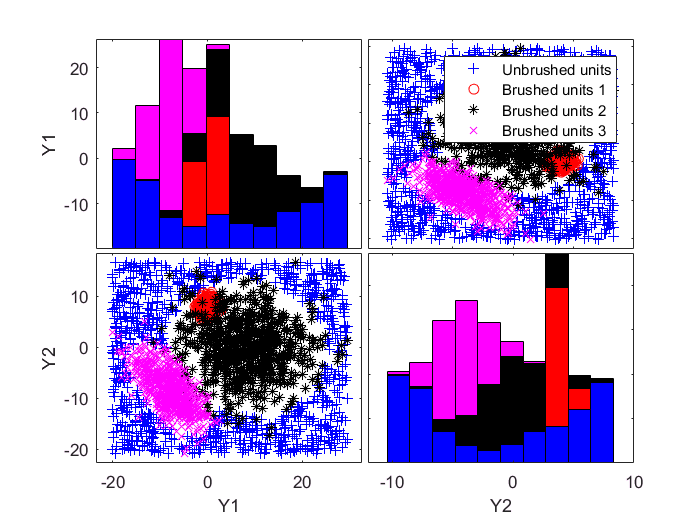

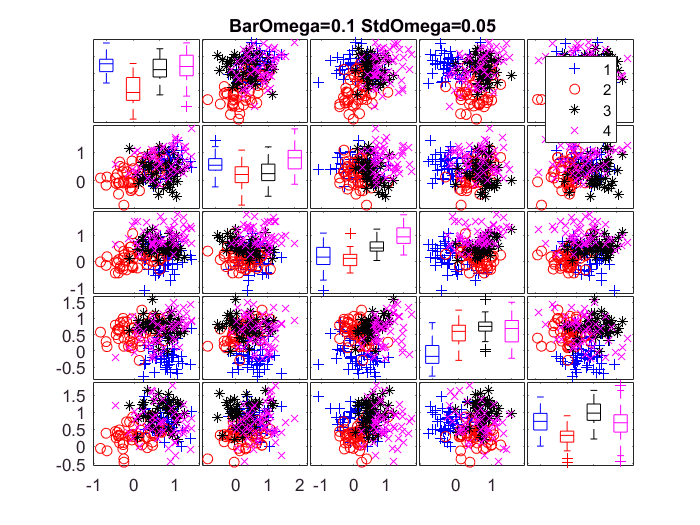


spmplot(X,id,[],'box');
set(gcf,'name',['BarOmega=' num2str(BarOmega) ' StdOmega=' num2str(StdOmega)])
title(['BarOmega=' num2str(BarOmega) ' StdOmega=' num2str(StdOmega)])
figure
spmplot(X1,id1,[],'box');
set(gcf,'name',['BarOmega=' num2str(BarOmega) ' StdOmega=' num2str(StdOmega1)])
title(['BarOmega=' num2str(BarOmega) ' StdOmega=' num2str(StdOmega1)])
cascade

disp('Comparison using interactive scatter plot matrices')

Comparison using interactive scatter plot matrices


disp('Please click on the legends to hide/show groups')

Please click on the legends to hide/show groups


## Contamination of the denoised M5data with uniform noise

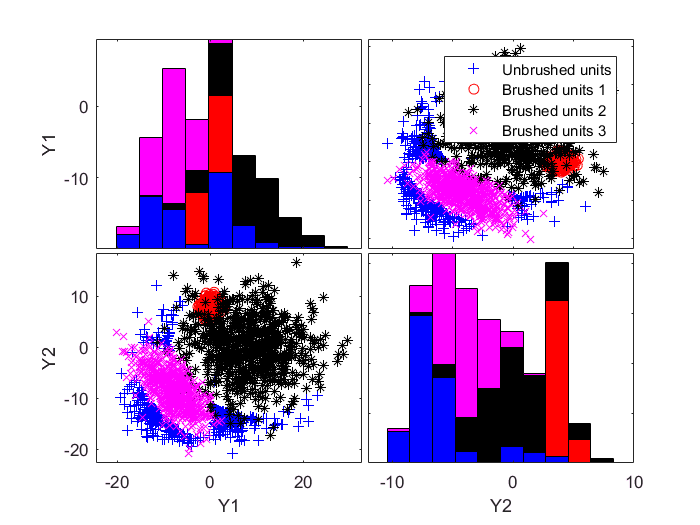

Y=load('M5data.txt');
Y1=Y(1:1800,1:2);
Mu=grpstats(Y1,Y(1:1800,3));

S=zeros(2,2,3);
S(:,:,1)=cov(Y1(1:360,:));
S(:,:,2)=cov(Y1(361:361+719,:));
S(:,:,3)=cov(Y1(361+720:1800,:));

pigen=[0.2;0.4;0.4];
% Add 1000 outliers from uniform using alpha=0.05
noisevars=0;
noiseunits=struct;
noiseunits.number=1000;
noiseunits.alpha=0.05;

% In this case the first argument which is supplied to simdataset is
% the original matrix X
[Y1withnoise,id]=simdataset(Y1, pigen, Mu, S,'noisevars',noisevars,'noiseunits',noiseunits);
spmplot(Y1withnoise,id);

## Contamination of the denoised M5data with uniform noise

Y=load('M5data.txt');
Y1=Y(1:1800,1:2);
Mu=grpstats(Y1,Y(1:1800,3));

S=zeros(2,2,3);
S(:,:,1)=cov(Y1(1:360,:));
S(:,:,2)=cov(Y1(361:361+719,:));
S(:,:,3)=cov(Y1(361+720:1800,:));

pigen=[0.2;0.4;0.4];
% Add 1000 outliers from \chi^2_{40} uniform using alpha=0.05
noisevars=0;
noiseunits=struct;
noiseunits.number=1000;
noiseunits.alpha=0.05;
noiseunits.typeout={'Chisquare40'};

% In this case the first argument which is supplied to simdataset is
% the original matrix X
[Y1withnoise,id]=simdataset(Y1, pigen, Mu, S,'noisevars',noisevars,'noiseunits',noiseunits);

in 10000 replicates in the interval [-20.1602--29.4659]
Number of values which was possible to generate is equal to 624
Please modify the type of outliers using option 'typeout' 
or increase input option 'alpha'
The value of alpha now is 0.05
Outliers have been generated according to Chisquare40


spmplot(Y1withnoise,id);